# Sistemas de primer orden

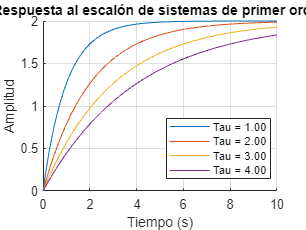

% Parámetros del sistema de primer orden
tau = [1, 2, 3, 4];  % Constante de tiempo (puedes modificar esta lista)
K = 2;              % Ganancia (ajusta este valor según tus necesidades)

% Tiempo de simulación
t = 0:0.01:10;  % Vector de tiempo de 0 a 10 segundos con paso de 0.01 segundos

% Inicializar una figura para las respuestas al escalón
figure;
hold on;

% Inicializar vectores para almacenar los resultados
tiempo_pico = zeros(length(tau), 1);
tiempo_establecimiento_95 = zeros(length(tau), 1);

% Iterar a través de diferentes valores de tau
for i = 1:length(tau)
    % Crear la función de transferencia del sistema de primer orden
    num = K;
    den = [tau(i), 1];
    sys = tf(num, den);  % Crear la función de transferencia
    
    % Calcular la respuesta al escalón del sistema
    y = step(sys, t);
    
    % Calcular parámetros característicos de la respuesta
    info = stepinfo(y, t);
    
    % Almacenar resultados
    tiempo_pico(i) = info.PeakTime;
    tiempo_establecimiento_95(i) = info.SettlingTime;
    
    % Graficar la respuesta al escalón
    plot(t, y, 'DisplayName', sprintf('Tau = %.2f', tau(i)));
end

title('Respuesta al escalón de sistemas de primer orden');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

% Agregar la leyenda
legend('Location', 'Best');


% Mostrar resultados en la ventana de comandos
disp('Resultados:');

Resultados:


disp('-----------------------------------------');

-----------------------------------------


disp(['Constante de Tiempo (Tau) | Tiempo de Pico | Tiempo de Establecimiento al 95%']);

Constante de Tiempo (Tau) | Tiempo de Pico | Tiempo de Establecimiento al 95%


disp('-----------------------------------------');

-----------------------------------------


for i = 1:length(tau)
    disp([tau(i), tiempo_pico(i), tiempo_establecimiento_95(i)]);
end

    1.0000   10.0000    3.9098

    2.0000   10.0000    7.2535

    3.0000   10.0000    8.7034

    4.0000   10.0000    9.1927

